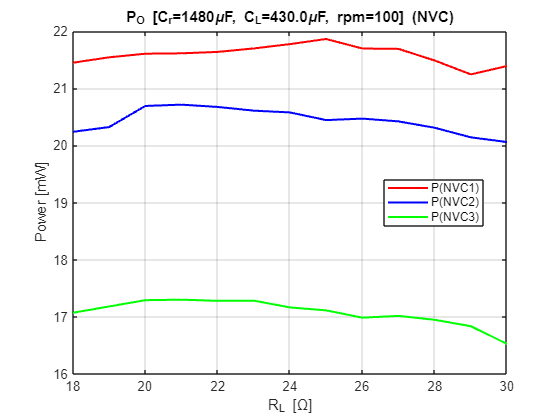


% Dati misurati (NVC1_100rpm.csv, NVC2_100rpm.csv, NVC3_100rpm.csv - tabella "C = 430 uF"):
% sweep della resistenza di carico R_L, C_m e rpm fissi.
% NOTA: i valori di potenza di NVC1 in questo file vanno divisi per 10
% (indicazione riportata esplicitamente nel CSV originale).
% CORREZIONE NVC1 a R_L = 19, 24, 27 Ohm: il CSV originale riportava Po = 21.54, 21.771,
% 21.687 (mW, prima della divisione per 10 di cui sopra), circa un ordine di grandezza
% sotto le celle vicine (~213-218): errore di esportazione della virgola decimale.
% Valori corretti moltiplicando per 10 (215.4, 217.71, 216.87), riportandoli in linea
% con l'andamento delle celle adiacenti.

C_r = 1480e-6;     % F - condensatore di filtro/raddrizzatore, fisso
C_L = 430e-6;      % F - condensatore di compensazione C_m, fisso durante lo sweep
rpm_b1 = 100;      % rpm fisso durante lo sweep

R_L = [18 19 20 21 22 23 24 25 26 27 28 29 30];   % Ohm (asse x)

Po_b1_mW = [214.456 215.4 216.029 216.094 216.345 216.949 217.71 218.601 216.938 216.87 214.842 212.407 213.871]/10;
Pi_b1_mW = [338.595 337.066 333.403 330.535 327.253 324.336 321.649 315.898 315.573 308.935 308.568 296.557 303.302]/10;

Po_b2_mW = [20.2369 20.3195 20.6889 20.7118 20.6714 20.6067 20.5755 20.4416 20.4674 20.4188 20.3076 20.1399 20.0578];
Pi_b2_mW = [32.1229 31.4554 31.7888 31.4200 31.0270 30.6647 30.4019 30.0225 29.8088 29.5543 29.1959 28.7335 28.4673];

Po_b3_mW = [17.0715 17.1813 17.2914 17.3003 17.2801 17.2830 17.1649 17.1129 16.9855 17.0164 16.9483 16.8362 16.5269];
Pi_b3_mW = [27.4533 27.1132 26.8714 26.7100 26.4043 26.1674 25.8166 25.5194 24.5946 24.9378 24.6800 24.3438 23.5175];

P_real_b1 = Po_b1_mW/1000;
P_real_b2 = Po_b2_mW/1000;
P_real_b3 = Po_b3_mW/1000;

P_in_b1 = Pi_b1_mW/1000;
P_in_b2 = Pi_b2_mW/1000;
P_in_b3 = Pi_b3_mW/1000;


figure;
plot(R_L, P_real_b1*1000, 'r-', 'LineWidth', 1.5);hold on;
plot(R_L, P_real_b2*1000, 'b-', 'LineWidth', 1.5);
plot(R_L, P_real_b3*1000, 'g-', 'LineWidth', 1.5);
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, C_L=%.1f\\muF, rpm=%.0f] (NVC)', C_r*1e6,C_L*1e6,rpm_b1));
xlabel('R_L [\Omega]');
ylabel('Power [mW]');
xlim([min(R_L), max(R_L)]);
legend(["P(NVC1)","P(NVC2)","P(NVC3)"], "Location","best");
hold off;

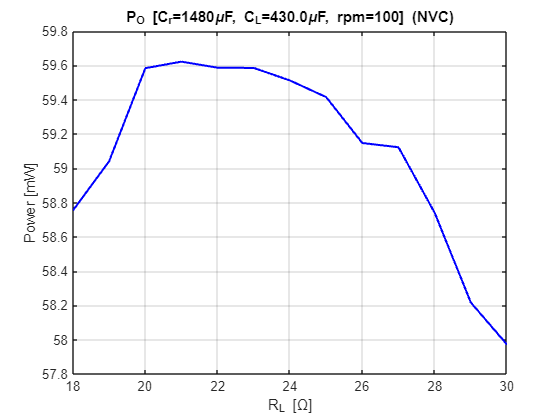


figure;
plot(R_L, (P_real_b1+P_real_b2+P_real_b3)*1000, 'b-', 'LineWidth', 1.5)
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, C_L=%.1f\\muF, rpm=%.0f] (NVC)', C_r*1e6,C_L*1e6,rpm_b1));
xlabel('R_L [\Omega]');
ylabel('Power [mW]');
xlim([min(R_L), max(R_L)]);
hold off;

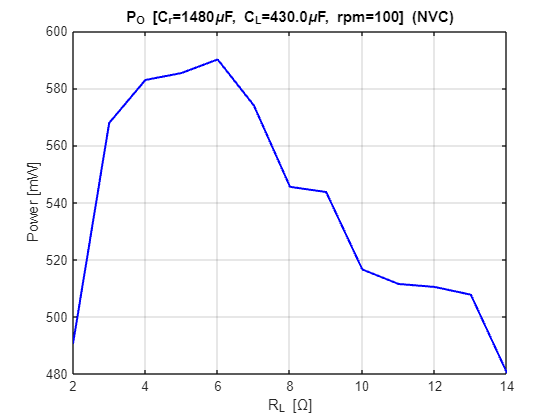



% Dati misurati con i tre bridge NVC gia' collegati in parallelo (NVC_1+2+3_100rpm.csv),
% C_m = 430 uF fisso, rpm = 100: mostrati in una figura separata perche' il range di R_L
% di questa misura (2-14 Ohm) e' diverso da quello dei bridge singoli sopra (18-30 Ohm).
% CORREZIONE: Pi a R_L = 8, 9, 13 Ohm (CSV: 86.438, 86.393, 77.38 mW) erano anomali di un
% ordine di grandezza rispetto alle celle vicine; corretti moltiplicando per 10
% (864.38, 863.93, 773.8), in linea con l'andamento delle celle adiacenti.

R_L_tot = [2 3 4 5 6 7 8 9 10 11 12 13 14];   % Ohm (asse x, misura con i tre bridge in parallelo)

Po_tot_mW = [490.581 567.814 582.849 585.299 590.049 573.973 545.494 543.655 516.552 511.503 510.453 507.749 480.366];
Pi_tot_mW = [1131.859 1097.585 1080.353 954.366 974.837 941.295 864.38 863.93 796.339 785.296 795.617 773.8 719.801];

P_real_tot_meas = Po_tot_mW/1000;
P_in_tot_meas = Pi_tot_mW/1000;

figure;
plot(R_L_tot, P_real_tot_meas*1000, 'b-', 'LineWidth', 1.5)
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, C_L=%.1f\\muF, rpm=%.0f] (NVC)', C_r*1e6,C_L*1e6,rpm_b1));
xlabel('R_L [\Omega]');
ylabel('Power [mW]');
xlim([min(R_L_tot), max(R_L_tot)]);
hold off;